clear;
load('C:\Users\Kikki\Archive\dataset\DC_mall\dc');

img = double(image);
x = 30;
y = 550;
cut_image = img(:,y:y+255,x:x+255);

% min(a,[],dim) 
% return the minimum value in the dimension range specified by dim in a
tmp_min = min(min(cut_image, [], 2), [], 3);
tmp_min = repmat(tmp_min, [1 256 256]);
cut_image = cut_image - tmp_min;

tmp_max = max(max(cut_image, [], 2), [], 3);
tmp_max = repmat(tmp_max, [1 256 256])

tmp_max = tmp_max(:,:,1) =

        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793        5793

cut_image = cut_image ./ tmp_max;
image = permute(cut_image, [2 3 1])

image = image(:,:,1) =

    0.2172    0.1873    0.2272    0.2348    0.2275    0.2474    0.2380    0.2494    0.1816    0.2123    0.1952    0.2099    0.2125    0.2253    0.2097    0.2099    0.2068    0.2184    0.2103    0.2192    0.2011    0.2094    0.2065    0.3074    0.5277    0.3078    0.2115    0.1921    0.1982    0.2099    0.1964    0.1883    0.2028    0.2008    0.2137    0.2144    0.1885    0.2090    0.1674    0.2002    0.1996    0.3730    0.3045    0.2330    0.2315    0.2608    0.2120    0.2296    0.2689    0.2103    0.2092    0.2187    0.2135    0.2165    0.2042    0.2513    0.2448    0.2220    0.2023    0.2263    0.2016    0.2589    0.2070    0.2695    0.1978    0.2166    0.1913    0.2235    0.2016    0.2127    0.1989    0.2270    0.3853    0.3309    0.2251    0.1709    0.1990    0.2056    0.2090    0.2218    0.2054    0.1749    0.1488    0.2077    0.2071    0.2308    0.2225    0.2814    0.2166    0.2258    0.2203    0.2192    0.1668    0.2672    0.2627    0.2382    0.1983    0.

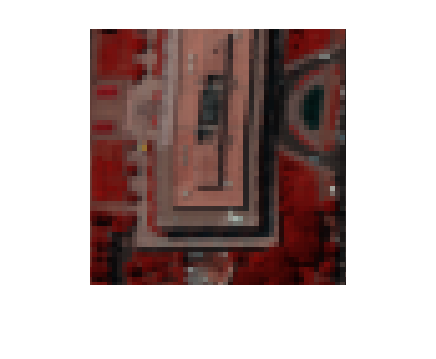

imshow(cat(3,image(:,:,57),image(:,:,27),image(:,:,17)))


image = cut_image;
image_noisy = image + randn(size(cut_image))*(70/255);
image_noisy(image_noisy < 0) = 0;
image_noisy(image_noisy > 1) = 1;
image_n = permute(image_noisy, [2 3 1])

image_n = image_n(:,:,1) =

    0.3648    0.5297    0.0194    0.4777    0.2367         0    0.1270    0.2625    0.0162    0.4062    0.1569    0.0703    0.7500         0         0         0         0    0.0825    0.5129    0.7587    0.0173         0    0.0622    0.6184    1.0000         0         0         0    0.4010         0    0.4596    0.4805         0    0.3556    0.0884    0.2771    0.1325    0.3337    0.3170    0.4907    0.4551    0.7801    0.0695    0.1858    0.1770    0.1794         0    0.1702         0    0.1923         0    0.3315         0    0.8024    0.1373    0.1767    0.7092    0.4229    0.9165    0.2586         0    0.1794    0.0704    0.1518         0    0.1288    0.0855    0.3324    0.2958         0         0    0.2904    0.5313    0.4601    0.5074    0.1562         0    0.0518         0    0.3430         0    0.3381    0.1525    0.1238    0.1896    0.0329         0    0.1745    0.4243    0.7926    0.0783    0.1005    0.5837    0.4012         0    0.3236         0  

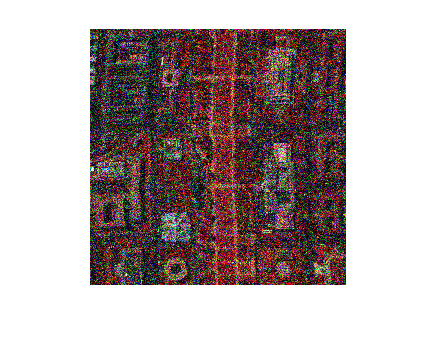

imshow(cat(3,image_n(:,:,57),image_n(:,:,27),image_n(:,:,17)))

save('C:\Users\Kikki\Desktop\denoising.mat','image','image_noisy');

image = permute(cut_image, [2 3 1])

image = image(:,:,1) =

    0.1712    0.1770    0.1876    0.1898    0.2054    0.1913    0.1876    0.1950    0.2154    0.1929    0.2019    0.1812    0.2326    0.2818    0.3094    0.2176    0.2489    0.2723    0.2056    0.1946    0.2138    0.2123    0.2399    0.2118    0.2434    0.2429    0.2546    0.2511    0.2423    0.2306    0.2763    0.3034    0.2659    0.2436    0.3036    0.1743    0.2456    0.2842    0.1191    0.0856    0.0750    0.0730    0.1639    0.1331    0.1357    0.1172    0.1598    0.1456    0.1571    0.0916    0.0856    0.3230    0.4905    0.4592    0.5020    0.4228    0.1412    0.0770    0.1668    0.1410    0.2396    0.4193    0.4106    0.4409    0.4596    0.2529    0.4371    0.2125    0.3007    0.0966    0.1125    0.0914    0.1271    0.1589    0.1754    0.1677    0.2323    0.3050    0.2666    0.2485    0.2052    0.2765    0.2473    0.2052    0.2553    0.2418    0.1904    0.1249    0.1377    0.1242    0.1606    0.1149    0.1569    0.1509    0.1770    0.1315    0.1474    0.

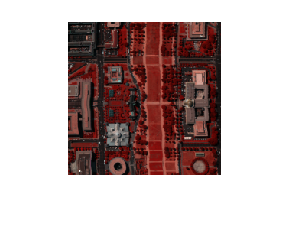

imshow(cat(3,image(:,:,57),image(:,:,27),image(:,:,17)))

p = psnr(double(pred_avg),image(:,:,1:191));

函数或变量 'pred_avg' 无法识别。

s = ssim(double(pred_avg),image(:,:,1:191));

fprintf('psnr: %f, ssim: %f  \n', p, s);
figure; imshow(cat(3,pred_avg(:,:,57),pred_avg(:,:,27),pred_avg(:,:,17)));

imwrite(cat(3,pred_avg(:,:,57),pred_avg(:,:,27),pred_avg(:,:,17)),'3D1.png');